# **Raman Spectrum Hydrogen Bond Deconvolution for (RSHBD)**

Smothing with Wavelet method and Baseline Correction with Quadratic Polynomial Fitting

Promoted by Xian-ze MENG, Fa-He Cao*, 28 Dec 2024, Sun Yat-sen University

clear
close all
global c NumTrials TrialError SpectraType
% Load Raman Spectra file in .csv or .xlsx types 
 FileName = uigetfile('*.csv;*.xlsx');    % Click this button to load data
RamanData = readtable(FileName); % disp(FileName) % from disk in xlsx or csv format
RamanshiftOri = table2array(RamanData(:,1)); % x axis of Raman Intensity % change Wavenumber formate to double
IntensityOri = table2array(RamanData(:,2)); % y axis of Raman Intensity % change Intensity formate to double
IntensityHeightOri = height(RamanshiftOri); 

% % with median filter, recursive sliding average, Savitsky-Golay, Fourier low-pass, or wavelet denoise 
% % (which requires the Matlab Wavelet Toolbox). To see the graphs on the right, 
% % right-click on the right panel and select "Disable synchronous scrolling". 
% % by Tom O'Haver 4/18/2023
% 
% PlotBeforeAndAfter= true; % Check this box to display smoothed signal as well as original.
% FrequencySpectra=true; % Check this box to display frequency spectra
% 
% % Set the x-axis scale expansion beginning and end points (0 - 100%)
% % startpc=1; % Percentage of data points to start data selection
% % endpc=100; % Percentage of data points to end data selection
% 
% RemoveSpikes=true; % Check this box to use median filter to remove spikes
% SpikeWidth=2; % Estimated spike width, in data points
% 
% SmoothType = 'Wavelet Denoise'; % "Wavelet Denoise"; % Select smoothing algrorithm
% 
% % For sliding average:
% SmoothWidth=20; % Smooth width for sliding average
% NumPasses=5; % Number of sliding average passes (1-5)
% SmoothEnds= true; % Click this box to smooth the ends of the data record.
% 
% % For Fourier low-pass filter:
% FrequencyCutoff=13; % Fourier filter cutoff frequency
% CutOffRate=6; % Fourier filter cutoff rate
% 
% % For Savitsky-Golay smooth only
% SGSmoothWidth=29; % Frame length for Savitsky-Golay
% PolynomialOrder=8; % Polynomial order must be less than the frame length
% 
% % For wavelet denoising only (requires Matlab Wavelet Toolox be installed)
% WaveletType="db4";
% Level=5; % The higher the level, the lower is the frequency divider between signal and noise
% % -------------------------------------------------------------------------------
% % startpoint=round(startpc*IntensityHeightOri./100);
% % endpoint=round(endpc*IntensityHeightOri./100);
% % x=table2array(RamanData(startpoint:endpoint,1));
% % rawy=table2array(RamanData(startpoint:endpoint,2));
% 
% x=RamanshiftOri;
% rawy=IntensityOri;
% 
% if RemoveSpikes==true
%     y=medianfilter(rawy,SpikeWidth);
% else
%     y=rawy;
% end
% 
% 
% switch WaveletType
%     case "BlockJS"
%         % sy=wdenoise(y,Level,'DenoisingMethod','BlockJS');
%         sy=wden(y,'minimaxi', 's', 'one',5, WaveletType);
%     case "bior5.5"
%         % sy=wdenoise(y,Level,'Wavelet','bior5.5','ThresholdRule','soft');
%         sy=wden(y,'minimaxi', 's', 'one',5, WaveletType);
%     case "coif2"
%         % sy=wdenoise(y,Level,'Wavelet','coif2','ThresholdRule','soft');
%         sy=wden(y,'minimaxi', 's', 'one',5, WaveletType);
%     case "sym8"
%         % sy=wdenoise(y,Level,'Wavelet','sym8','ThresholdRule','soft');
%         sy=wden(y,'minimaxi', 's', 'one',5, WaveletType);
%     case "db4"
%         % sy=wdenoise(y,Level,'Wavelet','db4','ThresholdRule','soft');
%         sy=wden(y,'minimaxi', 's', 'one',5, WaveletType);
%     % return
% end
% 
% figure(1)
% %clf
% if PlotBeforeAndAfter==true
%     plot(x,y,'k',x,sy,'r'); title(SmoothType);grid
%     legend('Original data','Smoothed data')
% else
%     plot(x,sy,'r'); title(SmoothType);grid
%     legend('Smoothed data')
% end
% 
% AreaRecovery=100.*trapz(x,sy)/trapz(x,y);
% xlabel(['Area recovery: ' num2str(AreaRecovery) ' %'])
% 
% % Optional Fourier spectrum plotted if FrequencySpectra checkbox is checked
% if FrequencySpectra==true
%     figure(2)
%     %clf
%     fyc=fft(sy);
%     syc=fyc .* conj(fyc);
%     minspec=min(syc);maxspec=max(syc);
%     psrange=1:length(fyc)/2;
%     psyc=real(syc(psrange));
%     loglog(psrange,psyc,'r','linewidth',1)
%     grid
%     axis([1 IntensityHeightOri/4 minspec maxspec])
%     title('Frequency spectra')
%     xlabel('Frequency')
%     legend('Smoothed data',"Location",'southwest')
%     if PlotBeforeAndAfter==true
%         fyc=fft(y);
%         syc=fyc .* conj(fyc);
%         minspec=min(syc);maxspec=max(syc);
%         psrange=1:length(fyc)/2;
%         psyc=real(syc(psrange));
%         hold on
%         loglog(psrange,psyc,'k','linewidth',1)
%         hold off
%         legend('Original data',' Smoothed data',"Location",'southwest')
%     end
% else
% end
% 
% % Extract Raman data range and Rebuild Intensity;
% IntensitySmooth = sy;
% 
% SpectraType = "Wavenumber"; % Chose the Spectrum type
% switch SpectraType
%     case "Wavenumber" % from 617.399 to 675.813 nm (2600.011275 to 3999.999822 cm-1);
%         [~,edge1] = min(abs(RamanshiftOri - 617.399)); % find the data series1 (2600 cm-1); 
%         [~,edgeA] = min(abs(RamanshiftOri - 625.118)); % find the data seriesA (2800 cm-1); 
%         [~,edgeB] = min(abs(RamanshiftOri - 666.800)); % find the data seriesB (3800 cm-1);
%         [~,edge2] = min(abs(RamanshiftOri - 675.813)); % find the data series2 (4000 cm-1);
%         RamanshiftCut = RamanshiftOri(edge1:edge2);
%         IntensityCut = IntensitySmooth(edge1:edge2); % new Raman Intensity;
%         FittingCut = RamanshiftOri([edge1:edgeA, edgeB:edge2]);
%         FittingInt = IntensitySmooth([edge1:edgeA, edgeB:edge2]);
%         RamanEdge = RamanshiftOri(edgeA:edgeB);
%         IntensityEdge = IntensitySmooth(edgeA:edgeB);
%         NumCut = length(IntensityCut);
%         NumEdge = length(IntensityEdge);
%         % WaveSequence1 = ( 
%     case "RamanShift" % from 2800 to 3800 cm-1
%         [~,edge1] = min(abs(RamanshiftOri - 2600)); % find the data series1 (2600 cm-1); 
%         [~,edgeA] = min(abs(RamanshiftOri - 2800)); % find the data seriesA (2800 cm-1);
%         [~,edgeB] = min(abs(RamanshiftOri - 3800)); % find the data seriesB (3800 cm-1);
%         [~,edge2] = min(abs(RamanshiftOri - 4000)); % find the data series2 (4000 cm-1);
%         RamanshiftCut = RamanshiftOri(edge1:edge2);
%         IntensityCut = IntensitySmooth(edge1:edge2); % new Raman Intensity;
%         FittingCut = RamanshiftOri([edge1:edgeA, edgeB:edge2]);
%         FittingInt = IntensitySmooth([edge1:edgeA, edgeB:edge2]);
%         RamanEdge = RamanshiftOri(edgeA:edgeB);
%         IntensityEdge = IntensitySmooth(edgeA:edgeB);
%         NumCut = length(IntensityCut);
%         NumEdge = length(IntensityEdge);
%     % otherwise
%         % ...
%     return
% end
% 
% figure(3)
% FittingP2 = polyfit(FittingCut,FittingInt,2);
% polyInt2 = polyval(FittingP2,RamanEdge);
% NewIntensity = IntensityEdge - polyInt2; % Intensity from 2800 to 3800 cm-1 after baseline correction.
% plot(RamanEdge,NewIntensity); hold on
% plot(RamanEdge,polyInt2,'.');
% plot(RamanshiftOri,IntensitySmooth);
% xlabel('Wavenumber(nm)','fontsize',15);
% % xlabel('Raman shift(cm^{-1})','fontsize',15)
% ylabel('Intensity(a.u.)','fontsize',15);

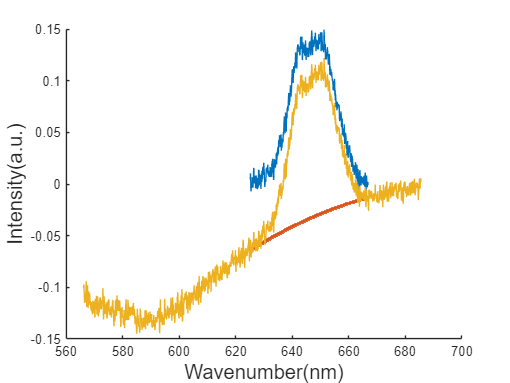

SpectraType = "Wavenumber"; % Chose the Spectrum type
switch SpectraType
    case "Wavenumber" % from 617.399 to 675.813 nm (2600.011275 to 3999.999822 cm-1);
        [~,edge1] = min(abs(RamanshiftOri - 617.399)); % find the data series1 (2600 cm-1); 
        [~,edgeA] = min(abs(RamanshiftOri - 625.118)); % find the data seriesA (2800 cm-1); 
        [~,edgeB] = min(abs(RamanshiftOri - 666.800)); % find the data seriesB (3800 cm-1);
        [~,edge2] = min(abs(RamanshiftOri - 675.813)); % find the data series2 (4000 cm-1);
        RamanshiftCut = RamanshiftOri(edge1:edge2);
        IntensityCut = IntensityOri(edge1:edge2); % new Raman Intensity;
        FittingCut = RamanshiftOri([edge1:edgeA, edgeB:edge2]);
        FittingInt = IntensityOri([edge1:edgeA, edgeB:edge2]);
        RamanEdge = RamanshiftOri(edgeA:edgeB);
        IntensityEdge = IntensityOri(edgeA:edgeB);
        NumCut = length(IntensityCut);
        NumEdge = length(IntensityEdge);
    case "RamanShift" % from 2800 to 3800 cm-1
        [~,edge1] = min(abs(RamanshiftOri - 2600)); % find the data series1 (2600 cm-1); 
        [~,edgeA] = min(abs(RamanshiftOri - 2800)); % find the data seriesA (2800 cm-1);
        [~,edgeB] = min(abs(RamanshiftOri - 3800)); % find the data seriesB (3800 cm-1);
        [~,edge2] = min(abs(RamanshiftOri - 4000)); % find the data series2 (4000 cm-1);
        RamanshiftCut = RamanshiftOri(edge1:edge2);
        IntensityCut = IntensityOri(edge1:edge2); % new Raman Intensity;
        FittingCut = RamanshiftOri([edge1:edgeA, edgeB:edge2]);
        FittingInt = IntensityOri([edge1:edgeA, edgeB:edge2]);
        RamanEdge = RamanshiftOri(edgeA:edgeB);
        IntensityEdge = IntensityOri(edgeA:edgeB);
        NumCut = length(IntensityCut);
        NumEdge = length(IntensityEdge);
    % otherwise
        % ...
    % return
end

figure(1); hold on
FittingP2 = polyfit(FittingCut,FittingInt,2);
polyInt2 = polyval(FittingP2,RamanEdge);
NewIntensity = IntensityEdge - polyInt2; % Intensity from 2800 to 3800 cm-1 after baseline correction.
plot(RamanEdge,NewIntensity);
plot(RamanEdge,polyInt2,'.'); 
plot(RamanshiftOri,IntensityOri); 
xlabel('Wavenumber(nm)','fontsize',15);
% xlabel('Raman shift(cm^{-1})','fontsize',15)
ylabel('Intensity(a.u.)','fontsize',15);

mint=min(RamanEdge);
maxt=max(RamanEdge);
dt=maxt-mint;

Width1=dt/10;
Width2=dt/5;
Width3=dt/5;
Width4=dt/10;
Width5=dt/10;

Height1=0.01;
Height2=0.05;
Height3=0.05;
Height4=0.01;
Height5=0.01;

switch SpectraType
    case "Wavenumber" 
       Position1=633.593; 
       Position2=641.149; 
       Position3=650.745; 
       Position4=656.815; 
       Position5=659.587; 
    case "RamanShift"
       Position1=3014; 
       Position2=3220; 
       Position3=3430; 
       Position4=3572; 
       Position5=3635; 
end

Peak1=[Height1 Position1 Width1];
Peak2=[Height2 Position2 Width2];
Peak3=[Height3 Position3 Width3];
Peak4=[Height4 Position4 Width4];
Peak5=[Height5 Position5 Width5];

% Starting point "start" has the form [position1 width1 position2 width2]
start=[Position1 Width1 Position2 Width2 Position3 Width3 Position4 Width4 Position5 Width5]  % automatically calculcated start (not very good)

start =   633.5930    4.1674  641.1490    8.3348  650.7450    8.3348  656.8150    4.1674  659.5870    4.1674


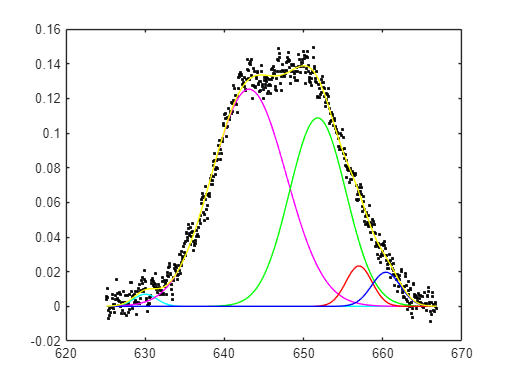

 
正在退出: 超过了函数计算的最大数目
 - 请增大 MaxFunEvals 选项。
 当前函数值: 0.140363 



parameter =   630.0136    3.4609  643.0995   11.0826  651.7776    8.4079  656.9878    3.8872  660.3917    4.2794


options = optimset('TolX',1);  % Determines how close the model must fit the data
% figure(2); hold on
figure
parameter=fminsearch(@(lambda)(fitgauss2animatedError(lambda,RamanEdge',NewIntensity')),start)

% % ===== BP-nural network rebuild/smooth =====
% trainRamanshift = RamanshiftOri';
% trainIntensity = IntensitySmooth';
% net = newff(trainRamanshift,trainIntensity,{10 10 10},{'tansig','purelin'},'trainlm');
% % BP parameter
% net.trainparam.goal        = 0.0000001;                                     % 训练目标：均方误差低于0.0001
% net.trainparam.show        = 100;                                         % 每训练100次展示一次结果
% net.trainparam.epochs      = 15000;                                       % 最大训练次数：15000.
% net.divideParam.trainRatio = 0.6;                                         % 用于训练的数据比例
% net.divideParam.valRatio   = 0.2;                                       % 用于验证过拟合的数据比例
% net.divideParam.testRatio  = 0.2;                                        % 用于测试的数据的比例
% net.trainparam.max_fail    = 6;                                           % 过拟合验证失败次数
% 
% [net,tr,net_y] = train(net,trainRamanshift,trainIntensity);  % 调用matlab神经网络工具箱自带的train函数训练网络y，net返回
% 
% % % ===========网络效果评估==================================
% % % 提取训练数据与测试数据                                                
% % train_net_y = net_y(:,tr.trainInd);                                       % 训练数据的预测值
% % test_net_y  = net_y(:,tr.testInd);                                        % 测试数据的预测值
% % train_y     = trainIntensity(:,tr.trainInd);                                           % 训练数据的真实值
% % test_y      = trainIntensity(:,tr.testInd);                                            % 测试数据的真实值
% % 
% % % 计算误差                                                              
% % train_err      = mean(abs(train_net_y(:)-train_y(:)))                     % 训练数据的误差
% % test_err       = mean(abs(test_net_y(:)-test_y(:)))                       % 测试数据的误差
% % train_err_rate = mean(abs((train_net_y(:)-train_y(:))./train_y(:)))       % 训练数据的误差比
% % test_err_rate  = mean(abs((test_net_y(:)-test_y(:))./test_y(:)))          % 测试数据的误差比
% % 
% % % 绘制拟合曲线图
% % figure
% % [out_size,sample_num] = size(trainIntensity);  % 输出的个数,样本个数
% % for i = 1 : out_size
% %     % 绘制训练数据第i个输出的拟合效果
% %     subplot(out_size,2,(i-1)*2+1);
% %     title(['训练数据-第',num2str(i),'个输出的拟合效果'])
% %     hold on 
% %     plot(1:size(train_y,2),train_y(i,:),'b')
% %     plot(1:size(train_net_y,2),train_net_y(i,:),'r')
% %     % 绘制测试数据第i个输出的拟合效果
% %     subplot(out_size,2,(i-1)*2+2);
% %     title(['测试数据-第',num2str(i),'个输出的拟合效果'])
% %     hold on 
% %     plot(1:size(test_y,2),test_y(i,:),'b')
% %     plot(1:size(test_net_y,2),test_net_y(i,:),'r')
% % end 
% % 
% %=============网络对新输入的使用==========================
% 
% IntensitySim = sim(net,RamanshiftOri');                  % BPNN Simulated Intensity
% figure;
% plot(RamanshiftOri,IntensitySim','.'); hold on
% % plot(RamanshiftOri,IntensityOri,'.');
% 
% 
% % ===== Quadratic polynomial fitting =====
% % figure;
% FittingP2 = polyfit(FittingCut,FittingInt,2);
% polyInt2 = polyval(FittingP2,RamanshiftCut);
% NewIntensity = IntensityCut - polyInt2; % Intensity from 2800 to 3800 cm-1 after baseline correction.
% plot(RamanshiftCut,polyInt2,'.');
% plot(RamanshiftCut,NewIntensity,'.');
% plot(RamanshiftOri,IntensitySmooth,'.');
% xlabel('Wavenumber(nm)','fontsize',15);
% % xlabel('Raman shift(cm^{-1})','fontsize',15)
% ylabel('Intensity(a.u.)','fontsize',15);
% 
% % ===== Cubic polynomial fitting =====
% % figure;
% % FittingP3 = polyfit(FittingCut,FittingInt,3);
% % polyInt3 = polyval(FittingP3,RamansiftCut);
% % plot(RamansiftCut,polyInt3,'.');
% % hold on
% % plot(RamanshiftOri,IntensityOri,'.');

% with a selection of different peak detectors and optional sharpening and least-squares curve fitting
% (which requires peakfit.m in the path). To see the graphs on the right, right-click on the right panel
% and select "Disable synchronous scrolling". Tom O'Haver 5/21/2023
ListPeaks=true; % Print out list of detected peak parameters (position, height, width, area)
LabelPeaks=false; % Check this box to number all detected peaks on the plot% Set the x-axis scale expansion beginning and end points (0 - 100%)
% startpc=1; % Percentage of data points to start data selection
% endpc=100; % Percentage of data points to end data selection

% Double-click any of the sliders to change their ranges if necessary
SymmetrizeFactor=0; % First-derivative "de-tailing" for skewed peaks
SmoothWidth=4; % Smoothing to skip false noise peaks. 
NumPasses=1; % Number of sliding average passes (1-5)

% Increasing this increases the sharpening but also increases noise
fdw=0.68 ; % Deconvolution width, as a fraction of width of narrowest peak
DA=4.2; % Denominator addition, helps to reduce noise and ringing
ShowRawData=true; % Show raW data points (red) with processed data (blue)
PeakDetector="PeaksAboveThreshold" ;
threshold=3; % Amplitude threshold, % of maximun
PeakSlope=1; % Lower values detect wider peaks (findpeaksG only)
PeakGroup=3; % Number of data points that defines the peak top

% Controls for optional least-squares peak fitting
FitDetectedPeaks=true; % Perform curve fit only detected peaks BEFORE SMOOTHING
PeakShape="Gaussian" ;
NumTrials=1; % Takes best of "NumTrials" curve fit trials
extra=0; % Shape parameter for variable-shape peaks (EMG, G/L blend, etc)
% -------------------------------------------------------------------------------

% Symmetrize by weighted first-derivative addition
ysym=NewIntensity+SymmetrizeFactor.*derivxy(RamanEdge,NewIntensity);

% Recursive sliding average smoothing
% AvaYsmooth=fastsmooth(ysym,SmoothWidth,NumPasses,1);
AvaYsmooth = NewIntensity;

if PeakDetector=="PeaksAboveThreshold"
    MaxSignal=max(AvaYsmooth);
    P=peaksatG(RamanEdge,AvaYsmooth,MaxSignal*threshold./100,PeakGroup);
    sizeP=size(P);
    NumPeaks=sizeP(1);
    disp([FileName   '   Peak detector: peaksatG.m'])
    if ListPeaks==true
        format short
        disp('    peak #   Position   Height     Width     Area')
        for n=1:NumPeaks
            disp(['    ' sprintf('%0.4g',n) '         ' sprintf('%0.4g',P(n,2)) '    '  sprintf('%0.4g',P(n,3))  '    '  sprintf('%0.4g',P(n,4)) '     '  sprintf('%0.4g',P(n,5))]);
        end
    end
end

figure(4)
clf
if LabelPeaks==true
    if ShowRawData==true
        plot(RamanEdge,AvaYsmooth,RamanEdge,NewIntensity,'.')
        legend('processed data','Raw data')
    else
        plot(RamanEdge,AvaYsmooth);
    end
    if SharpenPeaks==true
        title('Smoothed and Sharpened signal');
    else
        title('Selected data region');
    end
    grid
    text(P(:,2),P(:,3),num2str(P(:,1))) % Numbers peaks
else
    if ShowRawData==true
        plot(RamanEdge,AvaYsmooth,RamanEdge,NewIntensity,'.')
        legend('processed data','Raw data')
    else
        plot(RamanEdge,AvaYsmooth);
    end
    if SharpenPeaks==true
        title('Smoothed and Sharpened signal');
    else
        title('Selected data region');
    end
    grid
end
xlabel(['Number of peaks detected: ' num2str(NumPeaks) ])

if FitDetectedPeaks==true
    P=peaksatG(RamanEdge,AvaYsmooth,MaxSignal*threshold./100,PeakGroup);
    % Calculate first guess vector from peak detector results
    FirstGuess=[];
    for peak=1:NumPeaks
        FirstGuess=[FirstGuess P(peak,2) P(peak,4)];
    end
    % disp(FirstGuess)
    switch PeakShape
        case 'Gaussian'
            ShapeNumber=1 ;
        case 'Lorentzian'
            ShapeNumber=2 ;
        case 'Logistic distribution'
            ShapeNumber=3 ;
        case 'Pearson'
            ShapeNumber=4 ;
        case 'exponentially broadened Gaussian'
            ShapeNumber=5 ;
        case 'equal-width Gaussians'
            ShapeNumber=6 ;
        case 'equal-width Lorentzians'
            ShapeNumber=7 ;
        case 'exponentially broadened equal-width Gaussians'
            ShapeNumber=8 ;
        case 'exponential pulse'
            ShapeNumber=9 ;
        case 'Gaussian/Lorentzian blend'
            ShapeNumber=13 ;
    end
    figure(5)
    if SharpenPeaks==true
        [P,GOF]=peakfit([RamanEdge,AvaYsmooth],0,0,NumPeaks,ShapeNumber,extra,NumTrials,FirstGuess,0,0,1);
    else
        if SymmetrizeFactor==0
            [P,GOF]=peakfit([RamanEdge,NewIntensity],0,0,NumPeaks,ShapeNumber,extra,NumTrials,FirstGuess,0,0,1);
        else
            [P,GOF]=peakfit([RamanEdge,ysym],0,0,NumPeaks,ShapeNumber,extra,NumTrials,FirstGuess,0,0,1);
        end
    end

    if ListPeaks==true
        disp(['Fitting error=' num2str(GOF(1)) '%    R2= ' num2str(GOF(2))])
        disp('   peak #    Position  Height    Width     Area')
        for n=1:NumPeaks
            disp(['    ' sprintf('%0.4g',n) '         ' sprintf('%0.4g',P(n,2)) '    '  sprintf('%0.4g',P(n,3))  '    '  sprintf('%0.4g',P(n,4)) '     '  sprintf('%0.4g',P(n,5))]);
        end
    end
end

% =============================================================================

function SmoothY=fastsmooth(Y,w,type,ends)
% fastsmooth(Y,w,type,ends) smooths vector Y with smooth
%  of width w. Version 3.0, October 2016.
% The argument "type" determines the smooth type:
%   If type=1, rectangular (sliding-average or boxcar)
%   If type=2, triangular (2 passes of sliding-average)
%   If type=3, pseudo-Gaussian (3 passes of sliding-average)
%   If type=4, pseudo-Gaussian (4 passes of same sliding-average)
%   If type=5, multiple-width (4 passes of different sliding-average)
% The argument "ends" controls how the "ends" of the signal
% (the first w/2 points and the last w/2 points) are handled.
%   If ends=0, the ends are zero.  (In this mode the elapsed
%     time is independent of the smooth width). The fastest.
%   If ends=1, the ends are smoothed with progressively
%     smaller smooths the closer to the end. (In this mode the
%     elapsed time increases with increasing smooth widths).
% fastsmooth(Y,w,type) smooths with ends=0.
% fastsmooth(Y,w) smooths with type=1 and ends=0.
%
% Examples:
% fastsmooth([1 1 1 10 10 10 1 1 1 1],3)= [0 1 4 7 10 7 4 1 1 0]
% fastsmooth([1 1 1 10 10 10 1 1 1 1],3,1,1)= [1 1 4 7 10 7 4 1 1 1]
%
% x=1:100;
% y=randn(size(x));
% plot(x,y,x,fastsmooth(y,5,3,1),'r')
% xlabel('Blue: white noise.    Red: smoothed white noise.')
%
% Demonstration scripts and functions: SmoothExperiment.m,
% SmoothWidthTest.m, smoothdemo.m, SmoothOptimization.m,
% DemoSegmentedSmooth.m, DeltaTest.m, SmoothVsCurvefit.m
%
% Related functions: SegmentedSmooth.m, medianfilter.m, killspikes.m
% Download from
% https://terpconnect.umd.edu/~toh/spectrum/functions.html

% Copyright (c) 2012,2018 Thomas C. O'Haver
%
% Permission is hereby granted, free of charge, to any person obtaining a copy
% of this software and associated documentation files (the "Software"), to deal
% in the Software without restriction, including without limitation the rights
% to use, copy, modify, merge, publish, distribute, sublicense, and/or sell
% copies of the Software, and to permit persons to whom the Software is
% furnished to do so, subject to the following conditions:
%
% The above copyright notice and this permission notice shall be included in
% all copies or substantial portions of the Software.
%
% THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR
% IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY,
% FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE
% AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER
% LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM,
% OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN
% THE SOFTWARE.
if nargin==2, ends=0; type=1; end
if nargin==3, ends=0; end
switch type
    case 1
        SmoothY=sa(Y,w,ends);
    case 2
        SmoothY=sa(sa(Y,w,ends),w,ends);
    case 3
        SmoothY=sa(sa(sa(Y,w,ends),w,ends),w,ends);
    case 4
        SmoothY=sa(sa(sa(sa(Y,w,ends),w,ends),w,ends),w,ends);
    case 5
        SmoothY=sa(sa(sa(sa(Y,round(1.6*w),ends),round(1.4*w),ends),round(1.2*w),ends),w,ends);
end
end

% =============================================================================

function SmoothY=sa(Y,smoothwidth,ends)
w=round(smoothwidth);
SumPoints=sum(Y(1:w));
s=zeros(size(Y));
halfw=round(w/2);
L=length(Y);
for k=1:L-w
    s(k+halfw-1)=SumPoints;
    SumPoints=SumPoints-Y(k);
    SumPoints=SumPoints+Y(k+w);
end
s(k+halfw)=sum(Y(L-w+1:L));
SmoothY=s./w;
% Taper the ends of the signal if ends=1.
if ends==1
    startpoint=(smoothwidth + 1)/2;
    SmoothY(1)=(Y(1)+Y(2))./2;
    for k=2:startpoint
        SmoothY(k)=mean(Y(1:(2*k-1)));
        SmoothY(L-k+1)=mean(Y(L-2*k+2:L));
    end
    SmoothY(L)=(Y(L)+Y(L-1))./2;
end
end

% =============================================================================

function P=peaksatG(x,y,AmpThreshold,peakgroup)
% function P=peaksatG(x,y,AmpThreshold,peakgroup)
% peaksatG (peaks Above Threshold/Gaussian) lists every y value that (a)
% has lower y values on both sides and (b) is above the specified
% threshold. Returns a 2 x n matrix P with the x and y values of each peak,
% where n is the number of peaks detected. (Noisy data must be smoothed
% first). "Peakgroup" is the number points around the top part of the peak
% that are taken for measurement. If Peakgroup=0 the local maximum is takes
% as the peak height and position.
% See http://terpconnect.umd.edu/~toh/spectrum/Smoothing.html and
% http://terpconnect.umd.edu/~toh/spectrum/PeakFindingandMeasurement.htm
%
% Examples:
% peaksatG(0:.01:2,humps(0:.01:2),0,5)
% x=[0:.01:50];y=(1+cos(x)).^2;P=peaksatG(x,y,0,5)
% x=[0:.01:5];y=x.*sin(x.^2).^2;P=peaksatG(x,y,-1,5)
% x=[-10:.1:10];y=exp(-(x).^2);P=peaksatG(x,y,0.3,3)
%
% Find, measure, and plot peaks with variable unknown positions
%   x=-50:.2:50;
%   y=exp(-(x).^2)+exp(-(x+50*rand()).^2);
%   plot(x,y,'m.')
%   P=peaksatG(x,y,0.2,5);
%   text(P(:,2),P(:,3),num2str(P(:,1)))
%   disp('           peak #    Position    Height        Width         Area')
%   disp(P)
%
% Related functions:
% findpeaksG.m, findpeaksSG.m, findvalleys.m, findpeaksL.m, findpeaksb.m,
% findpeaksb3.m, findpeaksplot.m, peakstats.m, findpeaksnr.m,
% findpeaksGSS.m, ipeak.m findpeaksLSS.m, findpeaksfit.m, findsteps.m,
% findsquarepulse.m, idpeaks.m

% Copyright (c), 2022 Thomas C. O'Haver
%
% Permission is hereby granted, free of charge, to any person obtaining a copy
% of this software and associated documentation files (the "Software"), to deal
% in the Software without restriction, including without limitation the rights
% to use, copy, modify, merge, publish, distribute, sublicense, and/or sell
% copies of the Software, and to permit persons to whom the Software is
% furnished to do so, subject to the following conditions:
%
% The above copyright notice and this permission notice shall be included in
% all copies or substantial portions of the Software.
%
% THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR
% IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY,
% FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE
% AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER
% LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM,
% OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN
% THE SOFTWARE.
%
peakgroup=round(peakgroup);
n=round(peakgroup/2+1);
P=[0 0 0 0 0];
vectorlength=length(y);
peak=1;
for j=2:length(y)-1
    if y(j) > y(j-1)
        if y(j) > y(j+1)
            if y(j) > AmpThreshold  % if height of peak is larger than AmpThreshold
                xx=zeros(size(peakgroup));yy=zeros(size(peakgroup));
                for k=1:peakgroup % Create sub-group of points near peak
                    groupindex=j+k-n+2;
                    if groupindex<1, groupindex=1;end
                    if groupindex>vectorlength, groupindex=vectorlength;end
                    xx(k)=x(groupindex);
                    yy(k)=y(groupindex);
                end % for k=1:peakgroup,...
                if peakgroup>2
                    [Height,Position,Width]=gaussfit(xx,yy);
                    PeakX=real(Position);   % Compute peak position and height of fitted parabola
                    PeakY=real(Height);
                    MeasuredWidth=real(Width);
                    % if the peak is too narrow for least-squares technique to work
                    % well, just use the max value of y in the sub-group of points near peak.
                else
                    PeakY=max(yy);
                    pindex=val2ind(yy,PeakY);
                    PeakX=xx(pindex(1));
                    MeasuredWidth=0;
                end % if peakgroup>2,...
                % Construct matrix P. One row for each peak detected,
                % containing the peak number, peak position (x-value) and
                % peak height (y-value). If peak measurement fails and
                % results in NaN, or if the measured peak height is less
                % than AmpThreshold, skip this peak
                if isnan(PeakX) || isnan(PeakY) || PeakY<AmpThreshold
                    % Skip this peak
                else % Otherwise count this as a valid peak
                    P(peak,:) = [round(peak) PeakX PeakY MeasuredWidth  1.0646.*PeakY*MeasuredWidth];
                    peak=peak+1; % Move on to next peak
                end % if isnan...
            end % if y(j) > AmpThreshold,...
        end
    end
end % for j=2*round(smoothwidth/2)-1:...
end

% =============================================================================

function [index,closestval]=val2ind(x,val)
% Returns the index and the value of the element of vector x that is closest to val
% If more than one element is equally close, returns vectors of indicies and values
% Tom O'Haver (toh@umd.edu) October 2006
% Examples: If x=[1 2 4 3 5 9 6 4 5 3 1], then val2ind(x,6)=7 and val2ind(x,5.1)=[5 9]
% [indices values]=val2ind(x,3.3) returns indices = [4 10] and values = [3 3]
dif=abs(x-val);
index=find((dif-min(dif))==0);
closestval=x(index);
end

% =============================================================================

function [Height, Position, Width]=gaussfit(x,y)
% Converts y-axis to a log scale, fits a parabola
% (quadratic) to the (x,ln(y)) data, then calculates
% the position, width, and height of the
% Gaussian from the three coefficients of the
% quadratic fit.  This is accurate only if the data have
% no baseline offset (that is, trends to zero far off the
% peak) and if there are no zeros or negative values in y.
%
% Example 1: Simplest Gaussian data set
% [Height, Position, Width]=gaussfit([1 2 3],[1 2 1])
%    returns Height = 2, Position = 2, Width = 2
%
% Example 2: best fit to synthetic noisy Gaussian
% x=50:150;y=100.*gaussian(x,100,100)+10.*randn(size(x));
% [Height,Position,Width]=gaussfit(x,y)
%   returns [Height,Position,Width] clustered around 100,100,100.
%
% Example 3: plots data set as points and best-fit Gaussian as line
% x=[1 2 3 4 5];y=[1 2 2.5 2 1];
% [Height,Position,Width]=gaussfit(x,y)
% plot(x,y,'o',linspace(0,8),Height.*gaussian(linspace(0,8),Position,Width))
% Copyright (c) 2012, Thomas C. O'Haver

% To prevent problems from taking the log of zero or negative values,
% make the lowest value of y equal to 1% of the maximum value.
maxy=max(y);
for p=1:length(y)
    if y(p)<(maxy/100),y(p)=maxy/100;end
end % end of for p=1:length(y),
logabsy=log(abs(y));
sizex=size(x);
sizey=size(logabsy);
if (sizex(1)==sizey(1))
    [coef,~,MU]=polyfit(x',logabsy',2);
else
    [coef,~,MU]=polyfit(x,logabsy',2);
end
c1=coef(3);c2=coef(2);c3=coef(1);
% Compute peak position and height or fitted parabola
Position=-((MU(2).*c2/(2*c3))-MU(1));
Height=exp(c1-c3*(c2/(2*c3))^2);
Width=norm(MU(2).*2.35703/(sqrt(2)*sqrt(-1*c3)));
end

% =============================================================================

function [M,A]=autopeaks(x,y,SlopeThreshold,AmpThreshold,smoothwidth,peakgroup,smoothtype)
% Peak detection and height and area measurement for peaks of arbitrary
% shape in x,y time series data. Returns the peak table in the matrix P and
% the peak detection parameters in the vector A. The syntax autopeaks(x,y)
% works well in some cases, but if not try autopeaks(x,y,n), using
% different values of n (roughly the number of peaks that would fit into
% the signal record) until it detects the peaks that you want to measure.
% For the most precise control over peak detection, you can specify all the
% peak detection parameters by typing
% M=autopeaks(x,y,SlopeThreshold,AmpThreshold,smoothwidth,peakgroup)
%
% The syntax is similar syntax to autofindpeaks.m, in that that the peak
% detection parameters SlopeThreshold, AmpThreshold, smoothwidth,
% peakgroup, smoothtype can be omitted and the function will calculate
% initial values based on the number of data points and/or the optional
% peak density n (the last of 3 arguments after x and y). If you do specify
% all the peak detection parameters, they can be scalars or vectors with
% one entry for each segment (like findpeaskSG.m).
%
% Locates and measures the positive peaks in a noisy x-y time series data.
% Detects peaks by looking for downward zero-crossings in the first
% derivative whose upward slopes exceed SlopeThreshold. Returns matrix (M)
% containing peak number, the absolute peak height, peak-valley difference,
% perpendicular drop area, and the tangent skim area of each peak.
% Arguments "SlopeThreshold", "AmpThreshold" and "smoothwidth" control peak
% sensitivity of each segment. Higher values will neglect smaller features.
% "smoothwidth" is a vector of the widths of the smooths applied before
% peak detection; larger values ignore narrow peaks. If smoothwidth=0, no
% smoothing is performed. "peakgroup" is a vector of the number of points
% around the top part of the peak that are taken for initial estimate of
% the peak center and width (minimum 3). Note: this function uses
% smoothing only for peak detection; it performs measurements on the raw
% unsmoothed y data. If the data are noisy, it may be beneficial to smooth
% the y data yourself before calling autopeaks.m, using any smooth function
% of your choice.
%
% See https://terpconnect.umd.edu/~toh/spectrum/Integration.html
% http://terpconnect.umd.edu/~toh/spectrum/PeakFindingandMeasurement.htm
% (c) T.C. O'Haver, 2017.  Version 1, January, 2017
%
% The script testautopeaks.m will run all of the following examples with a
% 1-second pause between each, plotting the data and the peaks (by itself
% autopeaks.m does not plot, use autopeaksplot.m for that):
%
% Example 1: sin(x).^2 has theoretical peaks at x=0.5pi, 1.5pi, 2.5pi,
% 3.5pi..., with peak heights of 1.0 and peak areas of pi/2 = 1.5708.
%  disp('          Peak      Position    PeakMax    Peak-valley    Perp drop   Tan skim')
%  x=[0:.01:20]';y=sin(x).^2;autopeaks(x,y,0,0,5,5,1)
%
% Example 2: The built-in "humps" function has two peaks, no noise.
%  autopeaks(0:.01:2,humps(0:.01:2),0,0,1,1,1)
%
% Example 3: Series of peaks that get progressively taller and wider.
%  x=[0:.01:5]';y=x.*sin(x.^2).^2;autopeaks(x,y,0,0,5,5,1)
%
% Example 4: Like example 3, with random white noise added.
%  x=[0:.01:5]';y=.1.*randn(size(x))+x.*sin(-x.^2).^2;
%  autopeaks(x,y,.001,.5,15,15,1)
%
% Example 5; Like example 3, with added rising baseline.
%  x=[0:.01:5]';y=x+x.*sin(x.^2).^2;autopeaks(x,y,0,0,5,5,1)
%
% Example 6: Gaussian on linear baseline, theoretical area = 1.7725
%  x=[0:.1:10];y=2+x/10+exp(-(x-5).^2)+.01.*randn(size(x));
%  disp('          Peak      Position    PeakMax    Peak-valley    Perp drop   Tan skim')
%  autopeaks(x,y,0.0001,0.3,3,5,1)
%  Peak-valley and Tan skim are most accurate height and area measures.
%
% Example 7: Two overlapping Gaussians, zero baseline, theoretical area = 1.7725
%  x=[0:.05:10];y=exp(-(x-6).^2)+exp(-(x-3.5).^2)+.01.*randn(size(x));
%  disp('          Peak      Position    PeakMax    Peak-valley    Perp drop   Tan skim')
%  autopeaks(x,y,0.0001,0.5,8,6,1)
%  PeakMax and Perp drop are most accurate height and area measures.
%
% Example 8: Narrow Gaussian peak on sloping linear baseline, followed by
% much broader peak, theoretical heights 1 and 1, areas 1.6 and 31.9.
%  x=1:.2:150;
%  y=(150-x)./200+gaussian(x,30,1.5)+gaussian(x,90,30);
%  P=autopeaks(x,y,[0.001 .00005],[.6 .6],[5 120],[8 150],1)
%  PeakAreaError1=100.*((1.6-P(1,6))./1.6)
%  PeakAreaError2=100.*((31.9-P(2,6))./31.9)
%
% Similar functions: measurepeaks.m, autopeaksplot.m, autofindpeaks.m

% Permission is hereby granted, free of charge, to any person obtaining a copy
% of this software and associated documentation files (the "Software"), to deal
% in the Software without restriction, including without limitation the rights
% to use, copy, modify, merge, publish, distribute, sublicense, and/or sell
% copies of the Software, and to permit persons to whom the Software is
% furnished to do so, subject to the following conditions:
%
% The above copyright notice and this permission notice shall be included in
% all copies or substantial portions of the Software.
%
% THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR
% IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY,
% FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE
% AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER
% LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM,
% OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN
% THE SOFTWARE.
%
switch nargin
    % 'nargin' is the number of input arguments
    case 1  % One argument only
        % Assumne that the argument must be a matrix of data.
        % If DataMatrix is in the wrong transposition, fix it.
        datasize=size(x);
        if datasize(1)<datasize(2),x=x';end
        datasize=size(x);
        if datasize(2)==1, %  Must be ipeak(y-vector)
            y=x;
            x=[1:length(x)]'; % Create an independent variable vector
        else
            % Must be ipeak(DataMatrix)
            y=x(:,2);
            x=x(:,1); % Split matrix argument
        end
        % Calculate default values of peak detection parameters
        PeakDensity=20;
        % Estimate approx number of points in a peak half-width
        WidthPoints=length(y)/PeakDensity;
        SlopeThreshold=WidthPoints^-2;
        AmpThreshold=abs(min(y)+0.5*(max(y)-min(y)));
        smoothwidth=10;
        peakgroup=10;
        if peakgroup>100,peakgroup=100;end   % Keep peakgroup below 100
        if smoothwidth>100,smoothwidth=100;end   % Keep smoothwidth below 100
        smoothtype=3;
        A=[SlopeThreshold AmpThreshold smoothwidth peakgroup];
    case 2
        PeakDensity=20;
        % Estimate approx number of points in a peak half-width
        WidthPoints=length(y)/PeakDensity;
        SlopeThreshold=WidthPoints^-2;
        AmpThreshold=abs(min(y)+0.1*(max(y)-min(y)));
        smoothwidth=round(WidthPoints/3);
        peakgroup=round(WidthPoints/3);
        if peakgroup>100,peakgroup=100;end   % Keep peakgroup below 100
        if smoothwidth>100,smoothwidth=100;end   % Keep smoothwidth below 100
        smoothtype=3;
        A=[SlopeThreshold AmpThreshold smoothwidth peakgroup];
    case 3
        % Must be separate x and y data vectors plus a peak density
        % estimate.
        % Calculate values of peak detection parameters
        % arguments based on the peak density, PeakD
        PeakDensity=SlopeThreshold;
        % Estimate approx number of points in a peak half-width
        WidthPoints=length(y)/PeakDensity;
        SlopeThreshold=WidthPoints^-2;
        AmpThreshold=abs(min(y)+0.02*(max(y)-min(y)));
        smoothwidth=round(WidthPoints/3);
        peakgroup=round(WidthPoints/3);
        if peakgroup>100,peakgroup=100;end   % Keep peakgroup below 100
        if smoothwidth>100,smoothwidth=100;end   % Keep smoothwidth below 100
        smoothtype=3;
        A=[SlopeThreshold AmpThreshold smoothwidth peakgroup];
end

if peakgroup<3,peakgroup=3;end
% Find the peaks in the data
P=findpeaksSG(x,y,SlopeThreshold,AmpThreshold,smoothwidth,peakgroup,smoothtype);
sizeP=size(P);
NumPeaks=sizeP(1);
clear PeakHeight
clear M

% M=zeros(NumPeaks,6);
goodpeak=1;
for PeakNumber=1:NumPeaks
    PeakPos=P(PeakNumber,2);
    PeakWidth=P(PeakNumber,4);
    PeakIndex=val2ind(x,PeakPos);
    x1=val2ind(x,PeakPos-1.3.*PeakWidth); % Left-most end of peak
    x2=val2ind(x,PeakPos+1.3.*PeakWidth);  % Right-most end of peak
    Halfway=val2ind(x,PeakPos); % x-value of center of peak
    miny=min(y(x1:x2)); % Minimum y value of that region
    yy(x1:x2)=y(x1:x2)-miny;  % Subtract minimum from that region
    % Calculate height, peak-valley, and perpendicular drop area
    PeakMax=y(PeakIndex);
    LeftSideMinimum=min(yy(x1:Halfway));
    RightSideMinimum=min(yy(Halfway:x2));
    LeftValleyIndex=x1+val2ind(yy(x1:Halfway),LeftSideMinimum);
    RightValleyIndex=PeakIndex+val2ind(yy(Halfway:x2),RightSideMinimum);
    if RightValleyIndex(1)>length(x),RightValleyIndex(1)=length(x);end
    PDarea=sum(y(LeftValleyIndex(1):RightValleyIndex(1))).*(x(2)-x(1)); % Perpendicular Drop area
    PVHeight=PeakMax-(interp1([x(LeftValleyIndex(1)) x(RightValleyIndex(1))],[y(LeftValleyIndex(1)) y(RightValleyIndex(1))],PeakPos));
    interpy=interp1([x(LeftValleyIndex(1)) x(RightValleyIndex(1))],[y(LeftValleyIndex(1)) y(RightValleyIndex(1))],x(LeftValleyIndex(1):RightValleyIndex(1)));
    TSarea=sum((y(LeftValleyIndex(1):RightValleyIndex(1))-interpy).*(x(x1+1)-x(x1)));
    % [PeakNumber PeakPos PeakMax PVHeight]
    if PVHeight>AmpThreshold,
        M(goodpeak,:)=[goodpeak PeakPos  PeakMax PVHeight PDarea TSarea];
        goodpeak=goodpeak+1;
    end
end % for PeakNumber
x=1:.2:100;
y=gaussian(x,40,10)+gaussian(x,50,10)+.01.*randn(size(x));
A=[SlopeThreshold AmpThreshold smoothwidth peakgroup];
end

% =============================================================================

function ry=FourierFilter(xvector,yvector,centerfrequency,filterwidth,filtershape,filtermode)
% function ry=FourierFilter(xvector,yvector,centerfrequency,filterwidth,filtershape,filtermode)
% Computes fourier filter for signal yvector. Centerfrequency and
% filterwidth are the center frequency and width of the pass band, in
% harmonics, input arguments set the intital values of center frequency,
% filter width, shape, and filtermode (1-6):
% 1 = 'Band-pass'
% 2 = 'Lowpass'
% 3 = 'Highpass',
% 4 = 'Band-reject (notch)',
% 5 = 'Comb pass')
% 6 = 'Comb notch'
% 'filtershape' determines the sharpness of the cut-off.
%
% Adjust x and y vector shape to 1 x n (rather than n x 1)
xvector=reshape(xvector,1,length(xvector));
yvector=reshape(yvector,1,length(yvector));
fy=fft(yvector);
lft1=[1:(length(fy)/2)];
lft2=[(length(fy)/2+1):length(fy)];
% Compute filter shape.
if filtermode==1 % 'Band-pass'
    ffilter1=shapefunction(lft1,centerfrequency+1,filterwidth,filtershape);
    ffilter2=shapefunction(lft2,length(fy)-centerfrequency+1,filterwidth,filtershape);
    ffilter=[ffilter1,ffilter2];
end
if filtermode==2 % 'High-pass'
    centerfrequency=length(xvector)/2;
    ffilter1=shapefunction(lft1,centerfrequency+1,filterwidth,filtershape);
    ffilter2=shapefunction(lft2,length(fy)-centerfrequency+1,filterwidth,filtershape);
    ffilter=[ffilter1,ffilter2];
end
if filtermode==3 % 'Low-pass'
    centerfrequency=0;
    ffilter1=shapefunction(lft1,centerfrequency+1,filterwidth,filtershape);
    ffilter2=shapefunction(lft2,length(fy)-centerfrequency+1,filterwidth,filtershape);
    ffilter=[ffilter1,ffilter2];
end
if filtermode==4 % 'Band-reject (notch)'
    ffilter1=shapefunction(lft1,centerfrequency+1,filterwidth,filtershape);
    ffilter2=shapefunction(lft2,length(fy)-centerfrequency+1,filterwidth,filtershape);
    ffilter=1-[ffilter1,ffilter2];
end
if filtermode==5 % 'Comb pass'
    n=2;
    ffilter1=shapefunction(lft1,centerfrequency+1,filterwidth,filtershape);
    ffilter2=shapefunction(lft2,length(fy)-centerfrequency+1,filterwidth,filtershape);
    while n<50
        ffilter1=ffilter1+shapefunction(lft1,n*(centerfrequency+1),filterwidth,filtershape);
        ffilter2=ffilter2+shapefunction(lft2,length(fy)-n*(centerfrequency+1),filterwidth,filtershape);
        n=n+1;
    end
    ffilter=[ffilter1,ffilter2];
end
if filtermode==6 % 'Comb notch'
    n=2;
    ffilter1=shapefunction(lft1,centerfrequency+1,filterwidth,filtershape);
    ffilter2=shapefunction(lft2,length(fy)-centerfrequency+1,filterwidth,filtershape);
    while n<50
        ffilter1=ffilter1+shapefunction(lft1,n*(centerfrequency+1),filterwidth,filtershape);
        ffilter2=ffilter2+shapefunction(lft2,length(fy)-n*(centerfrequency+1),filterwidth,filtershape);
        n=n+1;
    end
    ffilter=1-[ffilter1,ffilter2];
end
if length(fy)>length(ffilter), ffilter=[ffilter ffilter(1)];end
ffy=fy.*ffilter;  % Multiply filter by Fourier Transform of signal
ry=real(ifft(ffy));

    function g = shapefunction(x,pos,wid,n)
        %  shapefunction(x,pos,wid,n) = peak centered on x=pos, half-width=wid
        %  x may be scalar, vector, or matrix, pos and wid both scalar
        %  Shape is Lorentzian (1/x^2) when n=0, Gaussian (exp(-x^2))
        %  when n=1, and becomes more rectangular as n increases.
        %  Example: shapefunction([1 2 3],1,2,1) gives result [1.0000    0.5000    0.0625]
        if n==0
            g=ones(size(x))./(1+((x-pos)./(0.5.*wid)).^2);
        else
            g = exp(-((x-pos)./(0.6.*wid)) .^(2*round(n)));
        end
    end
end

% =============================================================================

function y=savitzkyGolayFilt(x,N,DN,F,W,DIM)
%savitzkyGolayFilt Savitzky-Golay Filtering.
%   savitzkyGolayFilt(X,N,DN,F) filters the signal X using a Savitzky-Golay
%   (polynomial) filter.  The polynomial order, N, must be less than the
%   frame size, F, and F must be odd.  DN specifies the differentiation
%   order (DN=0 is smoothing). For a DN higher than zero, you'll have to
%   scale the output by 1/T^DN to acquire the DNth smoothed derivative of
%   input X, where T is the sampling interval. The length of the input X
%   must be >= F.  If X is a matrix, the filtering is done on the columns
%   of X.
%
%   Note that if the polynomial order N equals F-1, no smoothing
%   will occur.
%
%   savitzkyGolayFilt(X,N,DN,F,W) specifies a weighting vector W with
%   length F containing real, positive valued weights employed during the
%   least-squares minimization. If not specified, or if specified as
%   empty, W defaults to an identity matrix.
%
%   savitzkyGolayFilt(X,N,DN,F,[],DIM) or savitzkyGolayFilt(X,N,DN,F,W,DIM)
%   operates along the dimension DIM.
%
%   See also savitzkyGolay, FILTER, sgolayfilt

%   References:
%     [1] Sophocles J. Orfanidis, INTRODUCTION TO SIGNAL PROCESSING,
%              Prentice-Hall, 1995, Chapter 8.

%   Author(s): R. Losada
%   Copyright 1988-2004 The MathWorks, Inc.
%   $Revision: 1.11.4.4 $  $Date: 2009/08/11 15:47:54 $

narginchk(4,6);

% Check if the input arguments are valid
if round(F) ~= F, error(generatemsgid('MustBeInteger'),'Frame length must be an integer.'), end
if rem(F,2) ~= 1, error(generatemsgid('SignalErr'),'Frame length must be odd.'), end
if round(N) ~= N, error(generatemsgid('MustBeInteger'),'Polynomial order must be an integer.'), end
if N > F-1, error(generatemsgid('InvalidRange'),'The Polynomial order must be less than the frame length.'), end
if DN > N, error(generatemsgid('InvalidRange'),'The Differentiation order must be less than or equal to the Polynomial order.'), end

if nargin < 5 || isempty(W)
    % No weighting matrix, make W an identity
    W = ones(F,1);
else
    % Check for right length of W
    if length(W) ~= F, error(generatemsgid('InvalidDimensions'),'The weight vector must be of the same length as the frame length.'),end
    % Check to see if all elements are positive
    if min(W) <= 0, error(generatemsgid('InvalidRange'),'All the elements of the weight vector must be greater than zero.'), end
end

if nargin < 6, DIM = []; end

% Compute the projection matrix B
pp = fix(-F./2):fix(F./2);
B = savitzkyGolay(pp,N,DN,pp,W);

if ~isempty(DIM) && DIM > ndims(x)
    error(generatemsgid('InvalidDimensions'),'Dimension specified exceeds the dimensions of X.')
end

% Reshape X into the right dimension.
if isempty(DIM)
    % Work along the first non-singleton dimension
    [x, nshifts] = shiftdim(x);
else
    % Put DIM in the first dimension (this matches the order
    % that the built-in filter function uses)
    perm = [DIM,1:DIM-1,DIM+1:ndims(x)];
    x = permute(x,perm);
end

if size(x,1) < F, error(generatemsgid('InvalidDimensions'),'The length of the input must be >= frame length.'), end

% Preallocate output
y = zeros(size(x));

% Compute the transient on (note, this is different than in sgolayfilt,
% they had an optimization leaving out some transposes that is only valid
% for DN==0)
y(1:(F+1)/2-1,:) = fliplr(B(:,(F-1)/2+2:end)).'*flipud(x(1:F,:));

% Compute the steady state output
ytemp = filter(B(:,(F-1)./2+1),1,x);
y((F+1)/2:end-(F+1)/2+1,:) = ytemp(F:end,:);

% Compute the transient off
y(end-(F+1)/2+2:end,:) = fliplr(B(:,1:(F-1)/2)).'*flipud(x(end-(F-1):end,:));

% Convert Y to the original shape of X
if isempty(DIM)
    y = shiftdim(y, -nshifts);
else
    y = ipermute(y,perm);
end
end
